# Create cages from scratch

This guide explains how to produce a new cage file from raw information about the cages

## Example: simple arbitrary cage locations

This example will present a contrived scenario simply for purpose of illustrating how cage information can be specified and configured.

We'll create two cage groups with a few cages in each organised around a centre point. First let's just set up some simple criteria.

centre_e = 350400;
centre_n = 1068600;

no_groups = 2;
no_cages_per_group = 3;

group_distance_from_centre = [300, -300];
cage_distance_from_group_centre = [0, 100, 200];

We'll use these criteria for the individual cages

cage_length = 30;
cage_width  = 30;
cage_height = 10;
cage_depth  = 5;
cage_id     = '4c97b36c-bd67-44db-bfe7-15d6b3b298d2'; % arbitrary

cage_proportion    = 1/(no_groups*no_cages_per_group);
cage_in_production = true;

Note that for a circular cage, the length and width both refer to the diameter. The height is the total vertical length of the cage, whereas the depth is the vertical position of the cage mid-point below the water surface. For a surface cage, the depth should be half of the height. The cage proportion simply assumes - in this case - that each cage has a uniform stocking and therefore the total farm stocking is evenly distributed over all cages.

Now, instantiate an empty `Depomod.Layout.Site` object within which the information will be organised

site = Depomod.Layout.Site

site =   0 Site array with properties:

    cageGroups: {}
          path: ''

And finally, create the required group and cage objects according to our criteria

for g = 1:no_groups
    group_e = centre_e + group_distance_from_centre(g);
    group_n = centre_n;
    
    % initialise cage group object
    group  = Depomod.Layout.Cage.Group;

    for c = 1:no_cages_per_group
        cage_e = group_e;
        cage_n = group_n + cage_distance_from_group_centre(c);
        
        % initialise cage object
        cage = Depomod.Layout.Cage.Circle;

        cage.x            = cage_e;
        cage.y            = cage_n;
        cage.length       = cage_length;
        cage.width        = cage_width;
        cage.height       = cage_height;
        cage.depth        = cage_depth;
        cage.inputsId     = cage_id;
        cage.proportion   = cage_proportion;
        cage.inProduction = cage_in_production;
        
        % add cage to group
        group.cages{c} = cage;
    end

    % add group to site
    site.cageGroups{g} = group;
end

site

site =   2 Site array with properties:

    cageGroups: {[3 Depomod.Layout.Cage.Group]  [3 Depomod.Layout.Cage.Group]}
          path: ''

Okay, so it looks like we have an object with two groups and 3 cages per group.

## Plot new cages

We can plot the new cages by assigning them to a particular model run.

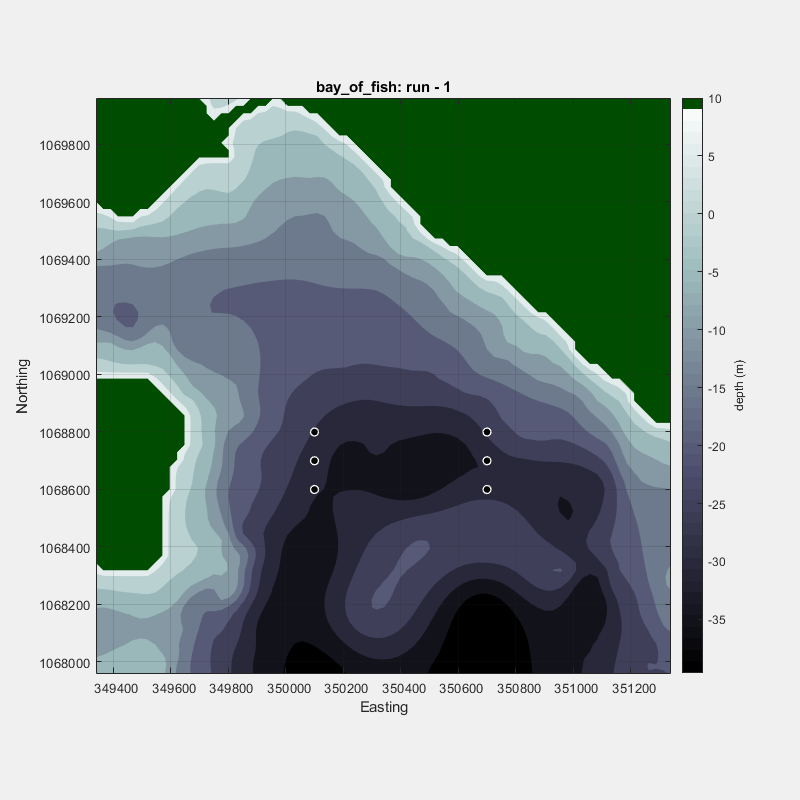

ans =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run = project.solidsRuns.first;
run.cages = site;

run.plot('impact', 0)

## Writing to file

Once the new cages are defined in Matlab they can be easily written to file. Since they did not originate from a particular file, however, a file name must be explicitly specified.This can be any full file path required, but a conventient short-cut is to use the run object path helpers.

site.toFile(run.cagesPath)